# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.1  基础知识技巧

#### 1.1.16 三维散点插值成曲面 

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

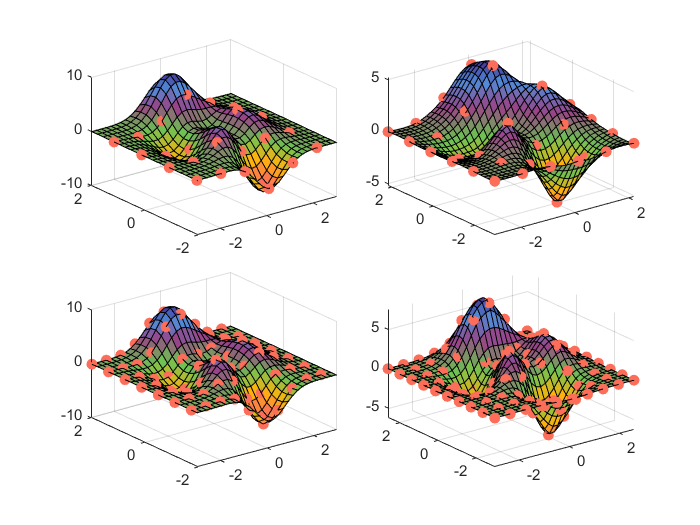

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 生成一个多峰曲面
M = 30;
[X, Y, Z] = peaks(M);
% 设置颜色
colormap(GenColormap(all_themes{1}, 64));
% 从曲面图中选择部分点来做插值，数据越多插值效果越好
steps = [5, 3];
tiledlayout(2, 2, 'TileSpacing', 'compact');
for ind = 1 : 2
    step = steps(ind);
    pos = 1:step:M;
    posX = X(pos, pos);
    posY = Y(pos, pos);
    posZ = Z(pos, pos);
    len = length(pos)*length(pos);
    x = reshape(posX, len, 1);
    y = reshape(posY, len, 1);
    z = reshape(posZ, len, 1);
    nexttile
    surf(X, Y, Z)
    hold on
    plot3(x, y, z, 'o', 'Color', all_colors(1, :), 'MarkerFaceColor', all_colors(1, :));
    hold off
    ylim([-2, 2]);
    % 调用 griddata 函数做插值，看看用我们选择的点来做插值是什么效果
    [Xi, Yi, Zi] = griddata(x, y, z, linspace(min(x), max(x), 30)', linspace(min(y), max(y), 30), 'v4');
    nexttile
    surf(Xi, Yi, Zi)
    hold on
    plot3(x, y, z, 'o', 'Color', all_colors(1, :), 'MarkerFaceColor', all_colors(1, :));
    hold off
end